# **Hand Tracking**

MATLAB contains muliple methods with which one can track moving objects. However, to both recognize and track a moving object requires a more specified approach and can benefit from the integration of live video feed from a video device. In this section we will learn how to not only how to integrate a built in webcam with MATLAB code, but also how to recognize features given either image or video input.

#### Image Processing

%%% Load handimage from a url 

url_img = 'http://apmonitor.com/pds/uploads/Main/hands.jpg';
outfilename = websave('hands.jpg',url_img)

outfilename = 'C:\Users\seant\MATLAB_new\hands.jpg'

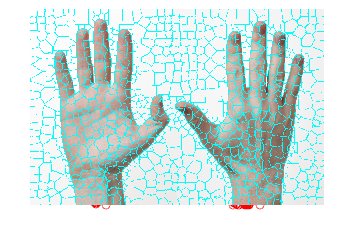


%%Read Image 
I = imread('hands.jpg');
 [L,N] = superpixels(I,1000); BW = boundarymask(L); 
 imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);


figure

%%Binarize 
Ibw = imbinarize(I);

%%Fill in holes in binarized image
Ibw = imfill(Ibw,'holes');

%%%Convert binary into logical array
Ilabel = logical(Ibw);

%%% calculate coordinates for X & Y centroids
stat = regionprops(Ilabel,'centroid');

%%%Computes superpixels for the image
[L,N] = superpixels(I,500)

L =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

N = 430

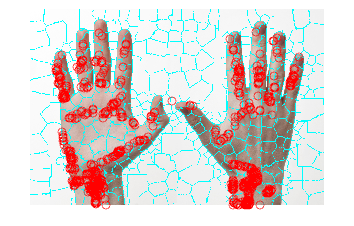


%%%%compute region boundaries for the input binary image
BW = boundarymask(L);
imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);  hold on;
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'ro');
end

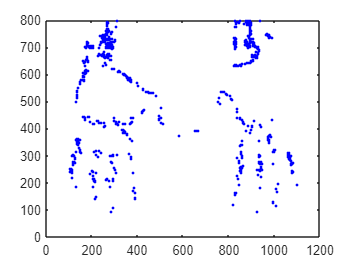

%%% Plot centroid points without background of hand image
figure
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'.b-');
    drawnow;
    hold on;
end


bwskel(Ibw)

ans = 800×1200×3 logical array
ans(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

#### Integration of Webcam with MATLAB

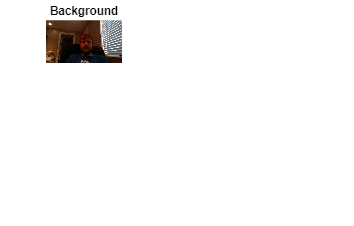

%%%%Clear any previous video object to allow camera to reaccess it 
%%%% If one exists and not cleared, then an error will be thrown
clear
imaqreset

%%%%Connect to video camera
vid=videoinput('winvideo',1);                                             %sets videoinput to the webcam, and the webcam device 1
figure(3)
preview(vid)                                                  %displays the webcam input

figure(1);

set(vid,'ReturnedColorspace','rgb')
pause(3);                                                                 % pause 2 seconds before snapshot of background image
IM1=getsnapshot(vid);                                                     %get snapshot from the webcam video and store to IM1 variable
figure(1);subplot(3,3,1);imshow(IM1);title('Background'); %open up a figure and show the image stored in IM1 variable

Note: If an external video device is to be used, then the input parameter in the "videoinput" line should be changed. 

# Varying Methods for Tracking Motion

With a video obejct created and in use, varying MATLAB methods can be used for tracking motion of specific body parts that are seen from live video.

#### Method 1: Face Detection with Cascade Object Detector

MATLAB has a built in object detector called Cascade which already has the capabilities to recognize and track faces from video input. 

%%% Code and associated originally from: 
%%% https://www.mathworks.com/help/vision/ug/face-detection-and-tracking-using-live-video-acquisition.html

% Create the face detector object.
faceDetector = vision.CascadeObjectDetector();

% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);


% From previous created video object, capture one frame to get its size.
pause(2)
vid.Timeout = 20

Summary of Video Input Object Using 'Integrated Webcam'.

   Acquisition Source(s):  input1 is available.

  Acquisition Parameters:  'input1' is the current selected source.
                           10 frames per trigger using the selected source.
                           'MJPG_1280x720' video data to be logged upon START.
                           Grabbing first of every 1 frame(s).
                           Log data to 'memory' on trigger.

      Trigger Parameters:  1 'immediate' trigger(s) on START.

                  Status:  Waiting for START.
                           0 frames acquired since starting.
                           0 frames available for GETDATA.



videoFrame = getsnapshot(vid);
frameSize = size(videoFrame);

% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30]);

runLoop = true;
numPts = 0;
frameCount = 0;

while runLoop && frameCount < 400

    % Get the next frame.
    videoFrame = getsnapshot(vid);
    videoFrameGray = im2gray(videoFrame);
    frameCount = frameCount + 1;

    if numPts < 10
        % Detection mode.
        bbox = faceDetector.step(videoFrameGray);

        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));

            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);

            % Save a copy of the points.
            oldPoints = xyPoints;

            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display detected corners.
            videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'white');
        end

    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);

        numPts = size(visiblePoints, 1);

        if numPts >= 10
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, inlierIdx] = estgeotform2d(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
            oldInliers    = oldInliers(inlierIdx, :);
            visiblePoints = visiblePoints(inlierIdx, :);

            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Display tracked points.
            videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');

            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
        end

    end

    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);

    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end

% Clean up.
clear vid;
release(videoPlayer);
release(pointTracker);
release(faceDetector);

#### Method 2: Hand Tracking using Foreground Detection

MATLAB also hasa builtin function that utilizes blob analysis in order to detect objects in the foreground of video input. This can thus be used to detect and track hand motion, which usually is foregrounded in video input of a person from a webcam. 

vidobj = imaq.VideoDevice('winvideo', 1);
detector = vision.ForegroundDetector(...
       'NumTrainingFrames', 50, ... % 
       'InitialVariance', (30/225).*2); % initial standard deviation of 30
blob = vision.BlobAnalysis(...
       'CentroidOutputPort', false, 'AreaOutputPort', false, ...
       'BoundingBoxOutputPort', true, ...
       'MinimumBlobAreaSource', 'Property', 'MinimumBlobArea', 250);
   shapeInserter = vision.ShapeInserter('BorderColor','White');
   videoPlayer = vision.VideoPlayer();
for n=1:500
     f  = step(vidobj);
     frame = rgb2gray(f);
     fgMask = step(detector, frame);
     bbox   = step(blob, fgMask);
       %out    = step(shapeInserter, frame, fgMask); % draw bounding boxes 
       step(videoPlayer, fgMask); % view results in the video player
end
release(vidobj);
release(videoPlayer);

#### Method 3: Color-based segmentation with Simulink

Using the MATLAB Simulink function with live input from a built in webcam, object's can be tracked based upon color. In the case of an example with body motion detection, the commonality of skin color between a subject's hands and face can be used to group these features together and then track them together. One such example model is provided below:

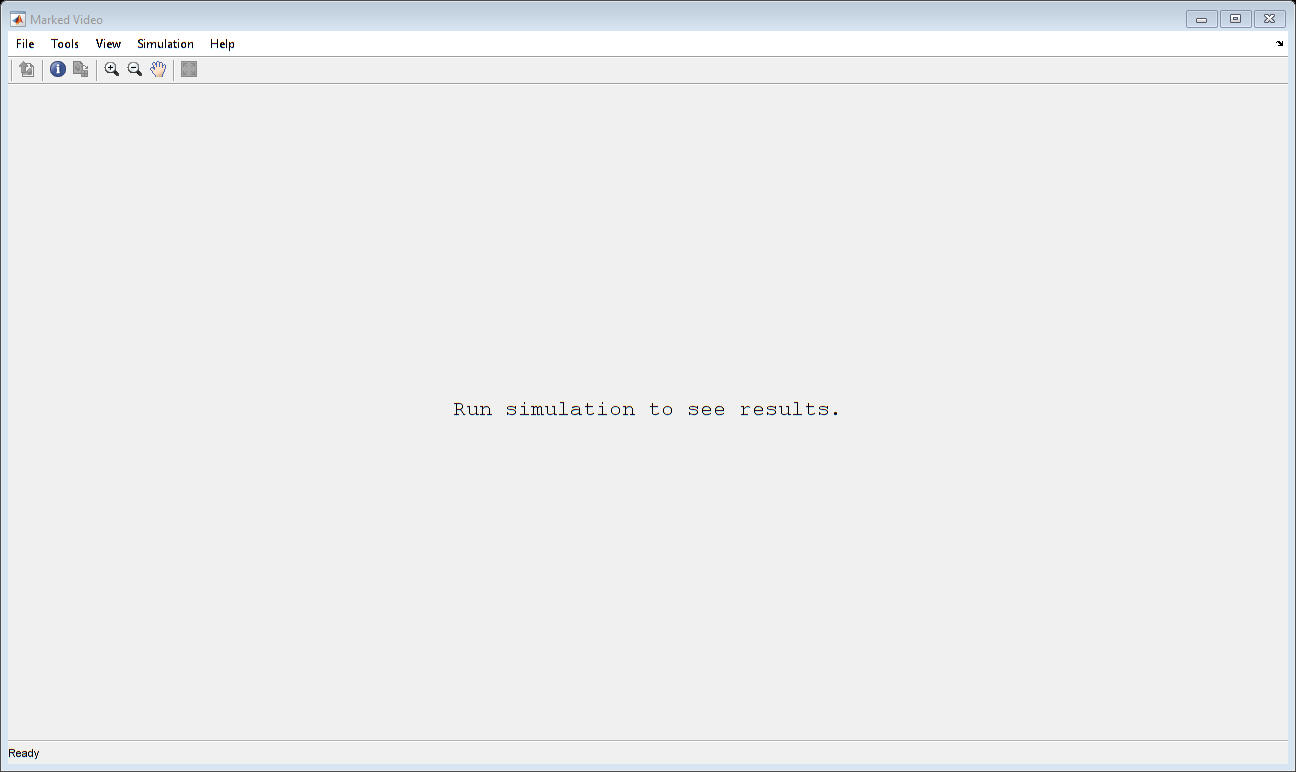

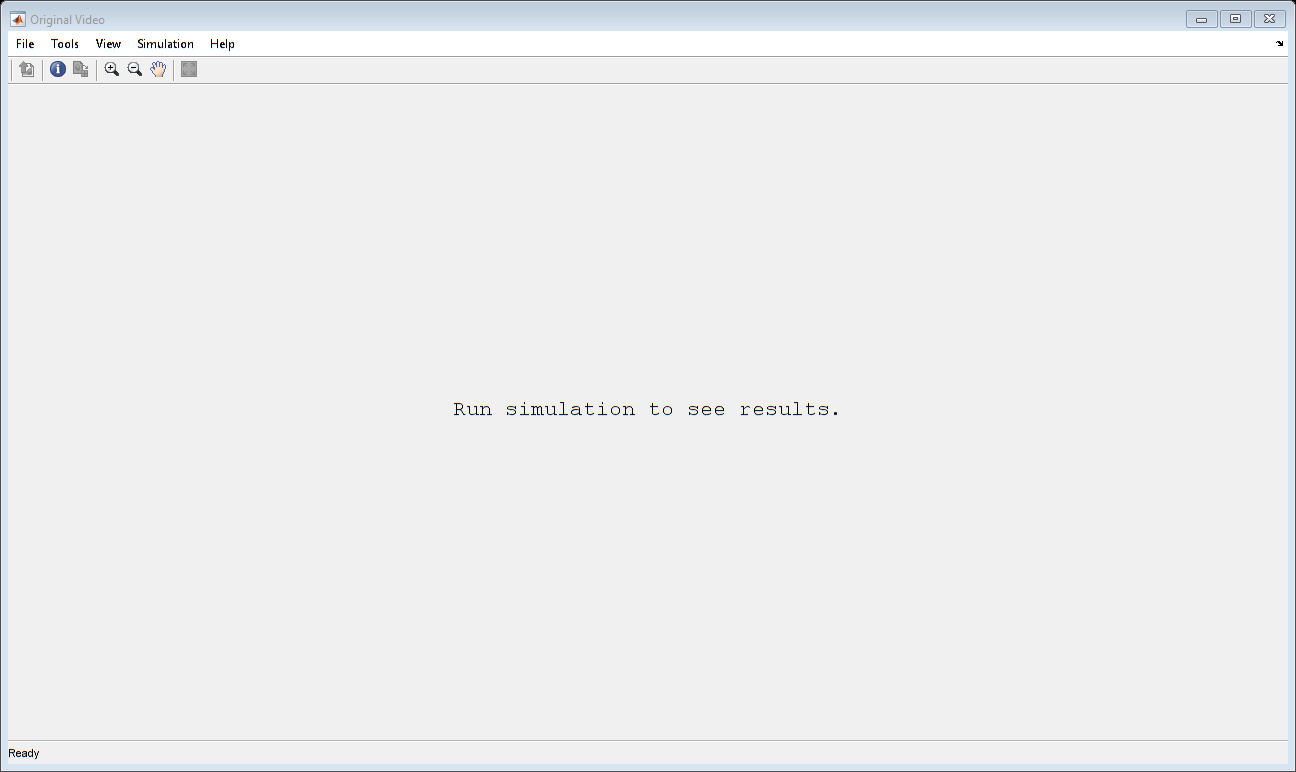

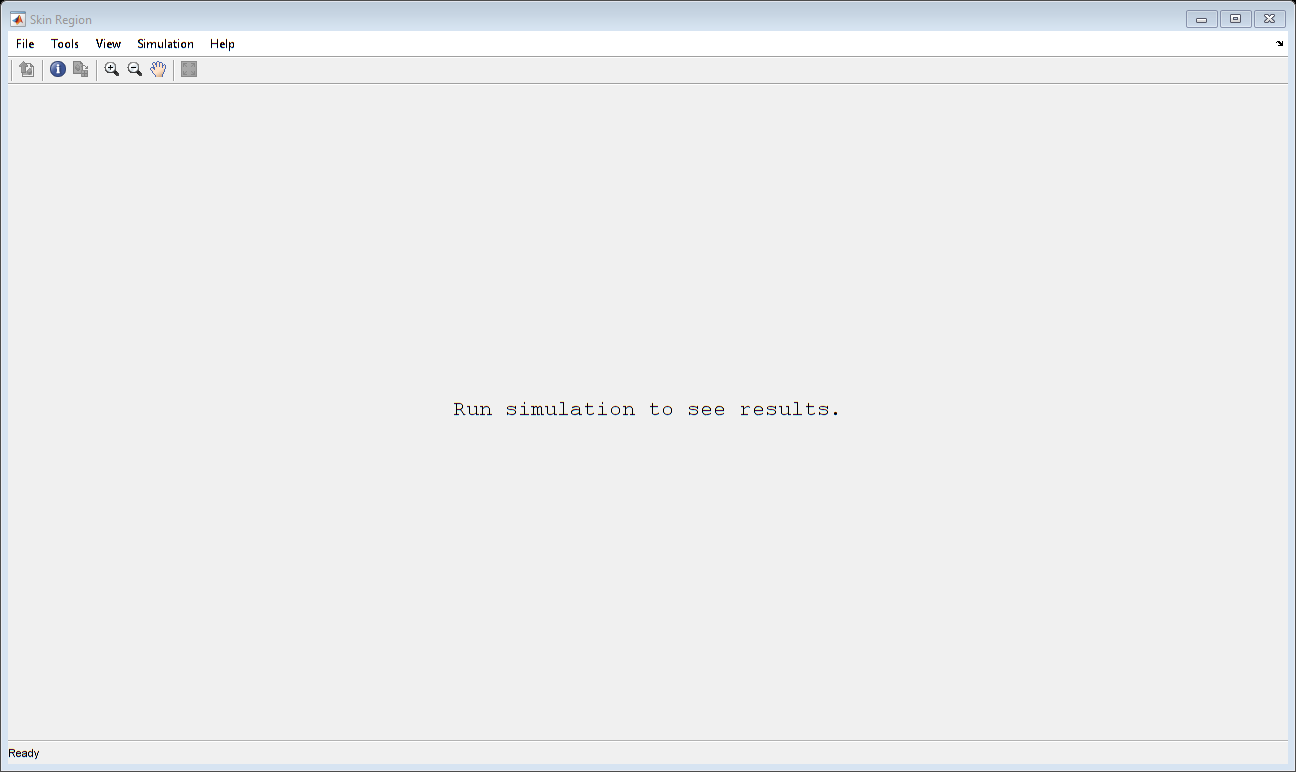

clear
vipcolorsegmentation_rgb_webcam_working